clear;  clc;
mFile = 'mask2m_16_16.mat';
load(mFile);  % mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);

% Reshape the data into a 2D matrix
x = reshape(mask2m, h*w, c);

% Select a signal for analysis
signalIndex = 1;  
y = x(signalIndex, :);  % Indicates the signalIndex signal

% Calculates the FFT of the original signal
fftOriginal = fft(y);

% Select a displacement
shiftAmount = 100;  % displacement

% applied displacement
yShifted = circshift(y, [0, shiftAmount]);
fftShifted = fft(yShifted);

% Calculates the frequency vector
Fs = 1000;  % Assumed sampling frequency
N = length(y);
f = Fs*(0:(N/2))/N;

% Find the maximum peak of the FFT amplitude spectrum, representing the major frequency component
[~, maxIndex] = max(abs(fftOriginal(1:N/2+1)));

mainFreq = f(maxIndex);

% Calculates the phase difference of the main frequency components
phaseOriginal = angle(fftOriginal(maxIndex))

phaseOriginal = 0

phaseShifted = angle(fftShifted(maxIndex))

phaseShifted = 0

phaseDiff = phaseShifted - phaseOriginal

phaseDiff = 0



% Draw FFT amplitude spectrum for verification
figure;
subplot (2,1,1);
plot(f, abs(fftOriginal(1:N/2+1)));

title('Original Signal FFT Magnitude');
xlabel('Frequency (Hz)');
ylabel('|FFT|');

subplot (2,1,2);
plot(f, abs(fftShifted(1:N/2+1)));

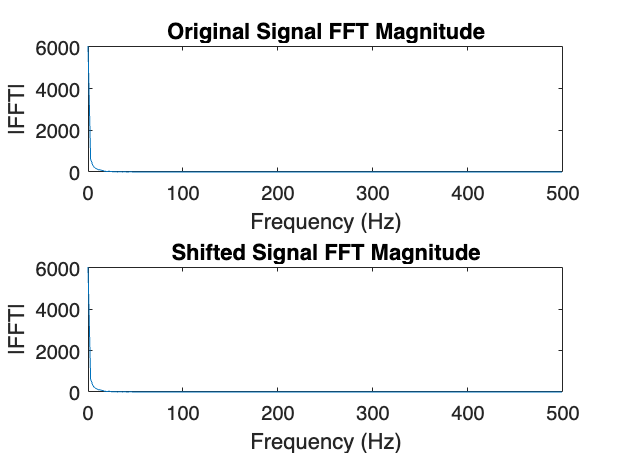

title('Shifted Signal FFT Magnitude');
xlabel('Frequency (Hz)');
ylabel('|FFT|');